# Suspension: PID Design

## System Diagram

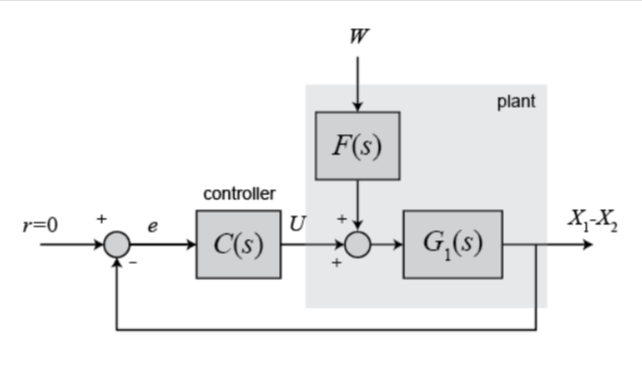

where $F\left(s\right)=G_{2\;} \left(s\right)/G_1 \left(s\right)$

## System Transfer function

% system parameter
m1 = 2500;
m2 = 320;
k1 = 80000;
k2 = 500000;
b1 = 350;
b2 = 15020;

nump=[(m1+m2) b2 k2];
denp=[(m1*m2) (m1*(b1+b2))+(m2*b1) (m1*(k1+k2))+(m2*k1)+(b1*b2) (b1*k2)+(b2*k1) k1*k2];
G1=tf(nump,denp);

num1=[-(m1*b2) -(m1*k2) 0 0];
den1=[(m1*m2) (m1*(b1+b2))+(m2*b1) (m1*(k1+k2))+(m2*k1)+(b1*b2) (b1*k2)+(b2*k1) k1*k2];
G2=tf(num1,den1);

% This is actually G2/G1
numf=num1;
denf=nump;
F=tf(numf,denf);

**Design Requirement**

- A step disturbance leads to a 5% overshoot

- Settling time less than 5sec for step disturbance

## Root Locus of Open loop G1

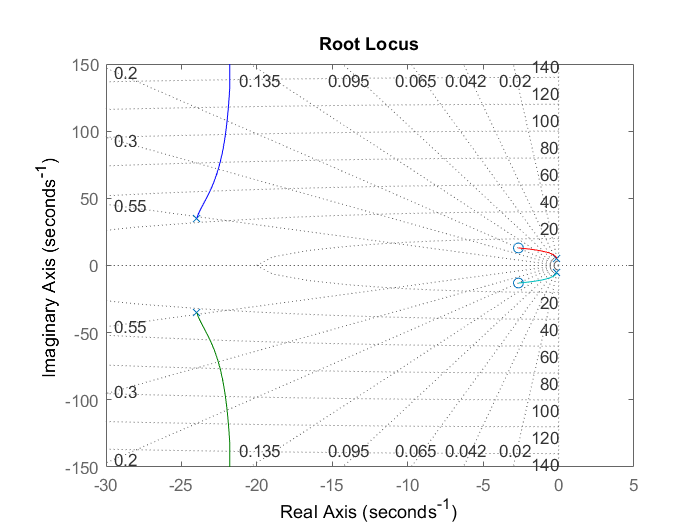

rlocus(G1);
sgrid;

The requirement asks for 5% overshoot which requires the zeta value to be larger than 0.707, and from the plot, a single gain could not meet the requirement, We need to add zeros so that the root locus can be pulled to the negative real axis, and we can use PID controller since it contains two zeros and one pole at origin. Note for the 5sec settling time which means that that the dominant poles should be larger than abs(-0.8).

## PID Design

We pick the zeros location at -2, and -4, And find the location of closed root location

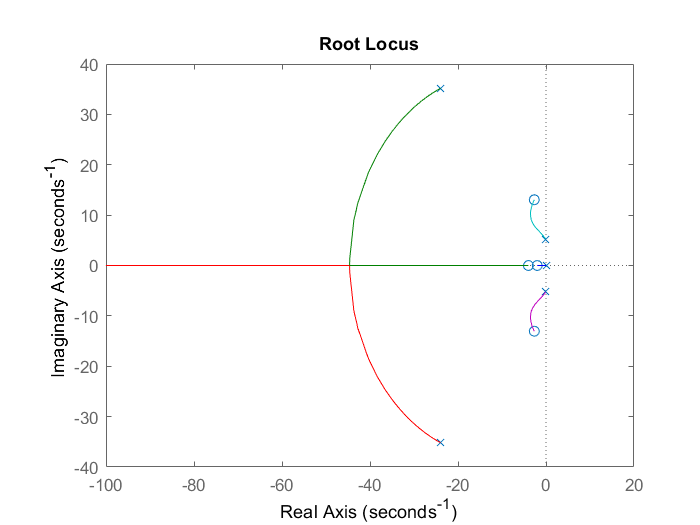

s = tf('s');
C = (s + 2)*(s + 4)/s;
rlocus(C*G1);

%[K, poles] = rlocfind(C*G1);

Corresponding K = 58000; 

## Close Loop response

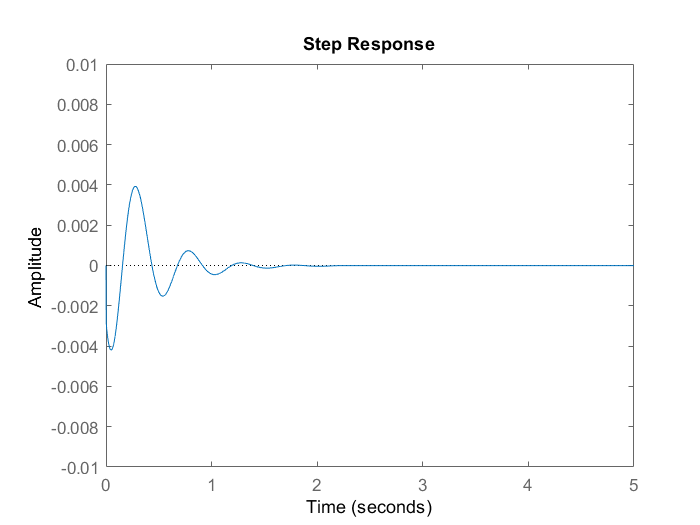

C = 8 * 58000 *C;
G_cl = feedback(G1, C);
step(0.1 * F*G_cl);
axis([0 5 -0.01 0.01])